# Paper3: 1st test

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
DataFolder3 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3TestingKernelData-RealLGN/']; % V1D2

addpath(DataFolder3)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath(SaveToFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Figures/Demo102823/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo102823/']; % V1D2
close all

## 2. Test for different x for E and I

first get basic function information

Too time comsuming. --->> using HPC

%AngleList = {'0.0'}; % only vertical for now
AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','LARGER'};

N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
N_HCinX = 4; N_HCinY = 4;
NPixX = 10; NPixY = 10;
N_HCs = 3; % shrink to 2*2
lgnSF = 2.5; lgnTF = 10;

Parameters of L4 kernels

MonocuFlag = false;
AngleTestAll = 0:7.5:180; % 0:7.5:22.5; % has to be multiples of 7.5
TestNum = length(AngleTestAll);

% Determine L4 Input from a range
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
    L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
    L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
    L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
    L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
    L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
    L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

Preparing tuning curves

TCDriveFlag = true;
if TCDriveFlag
    CtgrPix = ...
        [10,5
        10,3;
        %10,2;
        %10,1;
        9,2;
        %9,1;
        8,1;
        6,1];
    ODStr = 'Dr';
else
    CtgrPix = ...
        [10,16
        10,18;
        %10,19;
        %10,20;
        9,19;
        %9,20;
        8,20;
        6,20];
    ODStr = 'NoDr';
end

PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel
MarkerList = {'*','o','+','x','s','^','p'};
LW = [1,1/2,1,1/2,1,1/2,1];

AnglePlot = [AngleTestAll(floor(end/2)+1:end-1),...
    AngleTestAll(1:floor(end/2)), ...
    AngleTestAll(floor(end/2)+1)];
AngleUnique = 1:length(AnglePlot);

xtickAng = AnglePlot;
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,4) == 1
        xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

## Load data and plot figure for each combination of (xE, yE)

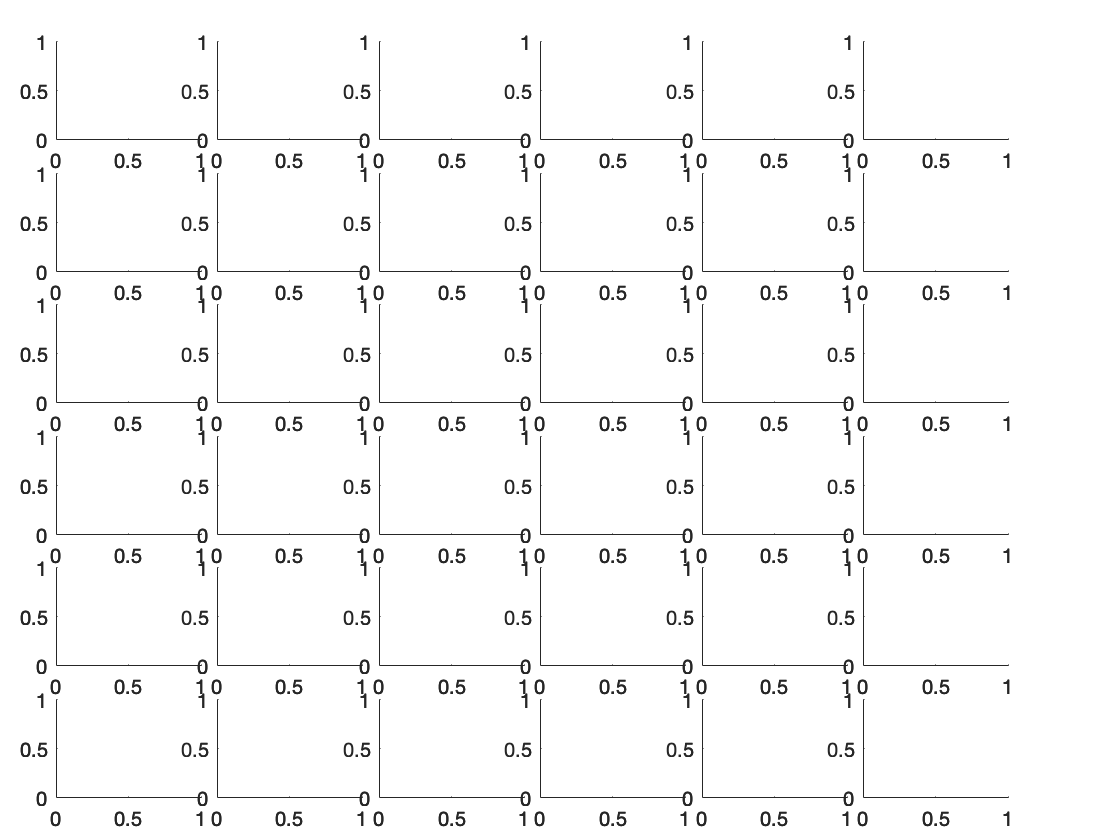

xEAll = 0:0.2:1; xIAll = 0:0.2:1;

figure(1)
ha1 = tight_subplot(length(xEAll),length(xIAll),[.04 .015],[.05 .05],[.05 .1]);

Fig3 = figure("Name",sprintf('TestKernel_XEYE_TuneCurve'),...
    'units','normalized','outerposition',[0,0,1,1]);
ha2 = tight_subplot(length(xEAll),length(xIAll),[.04 .015],[.05 .05],[.05 .1]);

for xEInd = 1:length(xEAll)
    for xIInd = 1:length(xIAll)
        fprintf('xE=%.1f, xI=%.1f\n',xEAll(xEInd),xIAll(xIInd))
        tic
        %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
        if MonocuFlag
            SaveStr = 'Monocu';
        else
            SaveStr = 'Binocu';
        end

LGN and L6 are blurred         

        L6smear = n_S_HC*0.25; LGNsmear = n_S_HC*0.2;
        TruncL6 = 0.33/(L6smear/n_S_HC); TruncLGN = 1;

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

        ParaEx = xEAll(xEInd); ParaEy = 1;
        ParaIx = xIAll(xIInd); ParaIy = 1;

        C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
        C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
        C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
        C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
        C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
        C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
        C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
        C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
        C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
            N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

        Conn_Reduc_Test = 5;
        Reduc_S = Conn_Reduc_Test*(1-CplxR); Reduc_C = Conn_Reduc_Test*CplxR;
        P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
        P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
        P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
        P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

        SaveStrUse = sprintf('%s-lgnSF%.1fTF%d_L6%.2f_%.2f_Ereduc%d_xE%.1fxI%.1fyE%.1fyI%.1f',...
            SaveStr,lgnSF,lgnTF,L6smear/n_S_HC,TruncL6,Conn_Reduc_Test,ParaEx,ParaIx,ParaEy,ParaIy);


load data

        load([SaveToFolder sprintf('RealLGN-NESSs_%s.mat',SaveStrUse)],...
            'LDEOutAll','AngleTestAll')
        TestId = 7; % for 45 deg

fig1: 45 deg NESS

%         figure(1)
%         axes(ha1((xEInd-1)*length(xIAll) + xIInd));
%         ShowField_Rec(...
%             LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR,...
%             ...%LDEOutAll{TestId}{end}.I,...
%             1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
%         title(sprintf('xE%.1f, xI%.1f',ParaEx,ParaIx))
% 
%         axis([0.5 20.5 10.5 30.5])
%         axis square
%         caxis([3 35]);
%         colorbar off
%         if mod(TestId,length(xIAll)) == 0
%             Pos1 = get(gca,'Position');
%             cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
%             set(cbr1,'FontSize',13)
%         end

fig2: tuning curves

        Fig3;
        axes(ha2((xEInd-1)*length(xIAll) + xIInd));
        hold on

        for PixInd = 1:length(CtgrPix)
            x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
            TuningCurve = zeros(size(AngleTestAll));
            TuningCurveI = zeros(size(AngleTestAll));
            for angId = 1:length(TuningCurve)
                PattS = LDEOutAll{angId}{end}.S;
                PattS = reshape(PattS,NPixY*N_HCOutY,NPixX*N_HCOutX);
                PattC = LDEOutAll{angId}{end}.C;
                PattC = reshape(PattC,NPixY*N_HCOutY,NPixX*N_HCOutX);
                PattI = LDEOutAll{angId}{end}.I;
                PattI = reshape(PattI,NPixY*N_HCOutY,NPixX*N_HCOutX);
                TuningCurve(angId) = ...
                    PattS(y,x) * (1-CplxR) + ...
                    PattC(y,x) * CplxR;
                TuningCurveI(angId) = ...
                    PattI(y,x);
            end
            TuningCurvePlot = ...
                [TuningCurve(floor(end/2)+1:end-1),...
                TuningCurve(1:floor(end/2)), ...
                TuningCurve(floor(end/2)+1)];
%             TuningCurvePlot = ...
%                 [TuningCurveI(floor(end/2)+1:end-1),...
%                 TuningCurveI(1:floor(end/2)), ...
%                 TuningCurveI(floor(end/2)+1)];
            plot(AngleUnique,TuningCurvePlot,'k','LineWidth',LW(PixInd),...)
                ...% 'Color',TunCurColor,
                'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
                'MarkerSize',8)
        end

        plot(AngleUnique,3.6*ones(size(AngleUnique)),'r','LineWidth',LW(1),'DisplayName','BG')

        set(gca,'FontSize',10)
        if xEInd == length(xEAll)
        xlabel('Grating Angle (deg)','FontSize',12);
        end
        if xIInd == 1
        ylabel('E firing rate','FontSize',12)
        end
        title(sprintf('xE%.1f, xI%.1f',ParaEx,ParaIx),'FontSize',12)

        xlim([1 25])
        %ylim([10 50])
        ylim([2 35]);
        set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
        %set(gca, 'FontSize',14)
        grid on

        if (xEInd == 1 && xIInd ==1)
        legend('Location','northwest','FontSize',10)
        end

    end
end

xE=0.0, xI=0.0
xE=0.0, xI=0.2
xE=0.0, xI=0.4
xE=0.0, xI=0.6
xE=0.0, xI=0.8
xE=0.0, xI=1.0
xE=0.2, xI=0.0
xE=0.2, xI=0.2
xE=0.2, xI=0.4
xE=0.2, xI=0.6
xE=0.2, xI=0.8
xE=0.2, xI=1.0
xE=0.4, xI=0.0
xE=0.4, xI=0.2
xE=0.4, xI=0.4
xE=0.4, xI=0.6
xE=0.4, xI=0.8
xE=0.4, xI=1.0
xE=0.6, xI=0.0
xE=0.6, xI=0.2
xE=0.6, xI=0.4
xE=0.6, xI=0.6
xE=0.6, xI=0.8
xE=0.6, xI=1.0
xE=0.8, xI=0.0
xE=0.8, xI=0.2
xE=0.8, xI=0.4
xE=0.8, xI=0.6
xE=0.8, xI=0.8
xE=0.8, xI=1.0
xE=1.0, xI=0.0
xE=1.0, xI=0.2
xE=1.0, xI=0.4
xE=1.0, xI=0.6
xE=1.0, xI=0.8
xE=1.0, xI=1.0


Save figures

FigName1 = sprintf('TuningCurve-realLGN_%s-%s',ODStr,SaveStr);
savefig(Fig3,[FigurePaperPath FigName1 '.fig']);


Print Figs

Fig3.PaperUnits = 'centimeters';
Fig3.PaperSize = [36,28];
Fig3.PaperOrientation = "landscape";
exportgraphics(Fig3,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all

## Check NESSs for Binocular

L6smear = n_S_HC*0.25;
TruncL6 = 0.33/(L6smear/n_S_HC);
Conn_Reduc_Test = 5;
ParaEx = 1;
ParaIx = 1;
ParaEy = 1;
ParaIy = 1;

MonocuFlag = false;
if MonocuFlag
    SaveStr = 'Monocu';
else
    SaveStr = 'Binocu';
end
DataStrUse = ...
    sprintf('%s-lgnSF%.1fTF%d_L6%.2f_%.2f_Ereduc%d_xE%.1fxI%.1fyE%.1fyI%.1f',...
    SaveStr,lgnSF,lgnTF,L6smear/n_S_HC,TruncL6,Conn_Reduc_Test,ParaEx,ParaIx,ParaEy,ParaIy);

load([SaveToFolder sprintf('RealLGN-NESSs_%s.mat',DataStrUse)],...
    'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','AngleTestAll')

Fig5 = figure("Name",sprintf('NESSs-Binocu'),...
    'units','normalized','outerposition',[0,0,1,1]);
ha3 = tight_subplot(3,4,[.04 .015],[.05 .05],[.05 .1]);
for AngId = 1:12
    axes(ha3(AngId));
    ShowField_Rec(...
        LDEOutAll{AngId}{end}.S*(1-CplxR)+LDEOutAll{AngId}{end}.C*CplxR,...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    title(sprintf('%.1f deg',AngleTestAll(AngId)))

    axis([0.5 20.5 10.5 30.5])
    axis square
    caxis([3 30]);
    colorbar off
    if AngId == 12
        Pos1 = get(gca,'Position');
        cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
        set(cbr1,'FontSize',13)
    end
end

Save figures

FigName1 = sprintf('NESSs-%s',DataStrUse);
savefig(Fig5,[FigurePaperPath FigName1 '.fig']);


Print Figs

Fig5.PaperUnits = 'centimeters';
Fig5.PaperSize = [36,28];
Fig5.PaperOrientation = "landscape";
exportgraphics(Fig5,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all